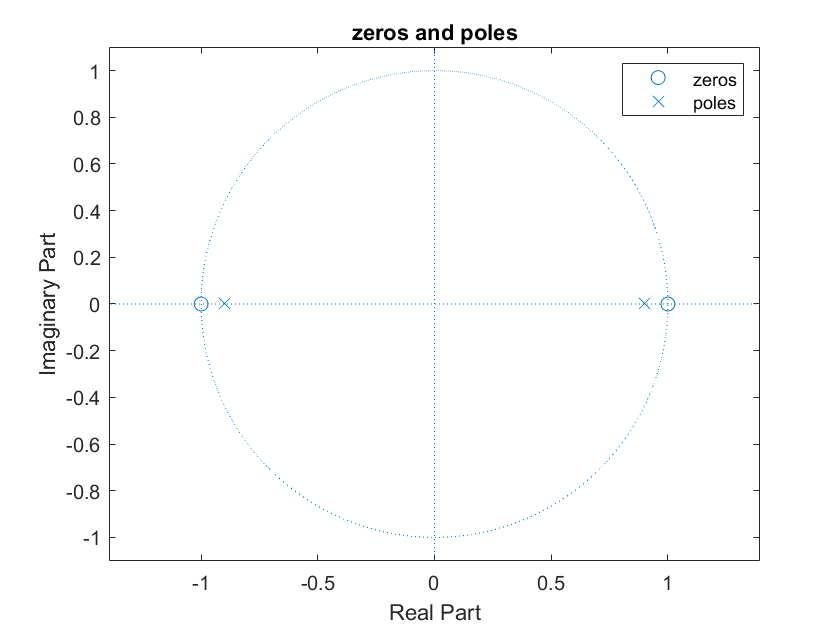

b=[1 0 -1];
z=roots(b);
a=[1 0 -0.81];
p=roots(a);

zplane(z,p)
title('zeros and poles')
legend('zeros','poles')


poly(z);
poly(p);
% [H,w]=freqz(b,a,n)
K=500;
k=0:K;
w=pi*k/K;
[H,w]=freqz(b,a,w);

dfp4(H,w)
[i,n]=impulseseq(0,7,0)

i = 1×8 logical array
   1   0   0   0   0   0   0   0


n =      0     1     2     3     4     5     6     7


h=filter(b,a,i)

h =     1.0000         0   -0.1900         0   -0.1539         0   -0.1247         0


% hv=0.9.^n
% error=max(abs(h-hv))

vc=0;
vr=[1.0566 -0.0556];
vp=[0.9 -0.9];
[vb,va]=residuez(vr,vp,vc)

vb =     1.0010    1.0010         0


va =     1.0000         0   -0.8100



v=filter(vb,va,i)

v =     1.0010    1.0010    0.8108    0.8108    0.6568    0.6567    0.5320    0.5320


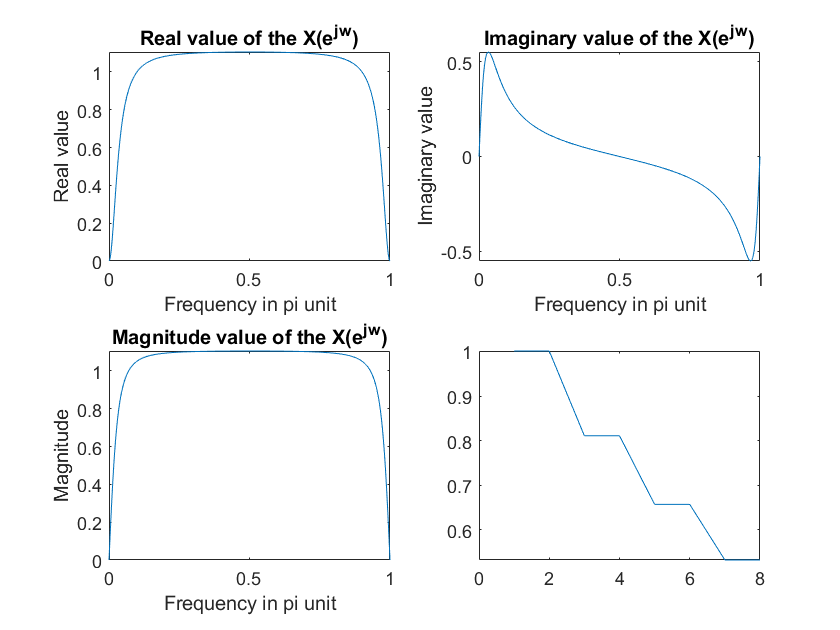

plot(v)